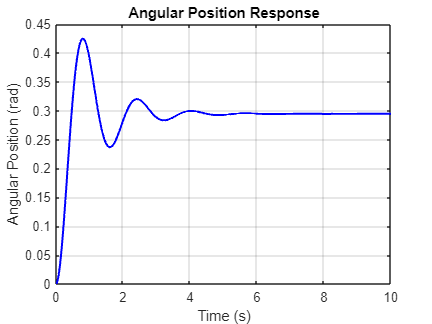

% Rotational Mass-Spring-Damper System with Proportional Controller

% Define system parameters
J = 0.1;  % Moment of inertia (kg*m^2)
b = 0.2;  % Damping coefficient (N*m*s/rad)
K = 1;    % Spring constant (N*m/rad)
setpoint = pi/4;  % Desired position (radians)

% Define controller parameters
Kp = 0.6;  % Proportional gain

% Simulation parameters
timestep = 0.01;  % Time step (s)
total_time = 10;   % Total simulation time (s)
time = 0:timestep:total_time;

% Initialize variables
theta = zeros(size(time));  % Angular position
omega = zeros(size(time));  % Angular velocity

% Simulate the system with proportional control
for i = 1:length(time)-1
    % Compute error (difference between setpoint and current position)
    error = setpoint - theta(i);
    
    % Compute control action (proportional term only)
    control_action = Kp * error;
    
    % Compute acceleration (from the equation of motion)
    alpha = (control_action - b * omega(i) - K * theta(i)) / J;
    
    % Update velocity and position using Euler's method
    omega(i+1) = omega(i) + alpha * timestep;
    theta(i+1) = theta(i) + omega(i+1) * timestep;
end

% Plot results
figure;

plot(time, theta, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Angular Position (rad)');
title('Angular Position Response');
grid on;

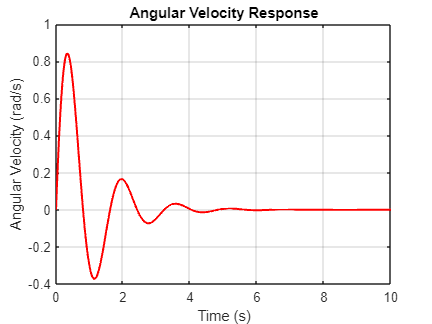



plot(time, omega, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Angular Velocity (rad/s)');
title('Angular Velocity Response');
grid on;